X(1:10,:) = [];
P(1:10,:) = [];
F(1:10,:) = [];
K(1) = [];

F = F (:,1:194);
X = X(:,1:194);
P = P(:,1:194);

a = length(K)

a = 200

USEE = ones([1,194]);
for nn = 0:a-1
    s = 1+nn*10;
    f = 10+nn*10;
    usee = 0.5.*K(nn+1).*X(s:f,:).^2;
    USEE = [USEE;usee];
end
USEE(1,:) = [];

% [k,x] = meshgrid(K,X);
% surf(x,k, USEE')


USEE(USEE == 0) = NaN;
X(X == 0) = NaN;
F(F == 0) = NaN;

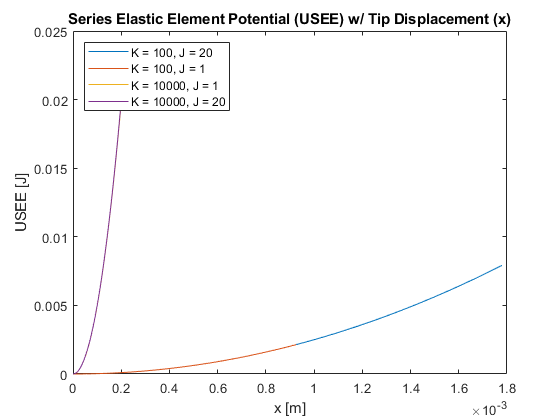

plot(X(10,:),USEE(10,:), 'DisplayName','K = 100, J = 20')
hold on
plot(X(1,:),USEE(1,:), 'DisplayName','K = 100, J = 1')
plot(X(1980,:),USEE(1980,:), 'DisplayName','K = 10000, J = 1')
plot(X(1990,:),USEE(1990,:), 'DisplayName','K = 10000, J = 20')
hold off
xlabel('x [m]')
ylabel('USEE [J]')
title('Series Elastic Element Potential (USEE) w/ Tip Displacement (x)')
legend('location','northwest')

% This loop doesn't work
[m,n] = size(USEE);
USEEKV = zeros(1,194);
klenm1 = length(K)-1;
for j=1:10
    for i=0:199
        s=j+10*i;
        useekv = USEE(s,:);
        USEEKV = [USEEKV ; useekv];
    end
end
USEEKV(1,:) = [];

[m,n] = size(F);
FKV = zeros(1,194);
klenm1 = length(K)-1;
for j=1:10
    for i=0:199
        s=j+10*i;
        fkv = F(s,:);
        FKV = [FKV ; fkv];
    end
end
FKV(1,:) = [];

USEEKVmax = max(USEEKV(1:200,:),[],2);
for i = 1:9
    s = 1+200*i;
    f = s + 199;
    useekvmax = max(USEEKV(s:f,:),[],2);
    USEEKVmax = [USEEKVmax, useekvmax];
end

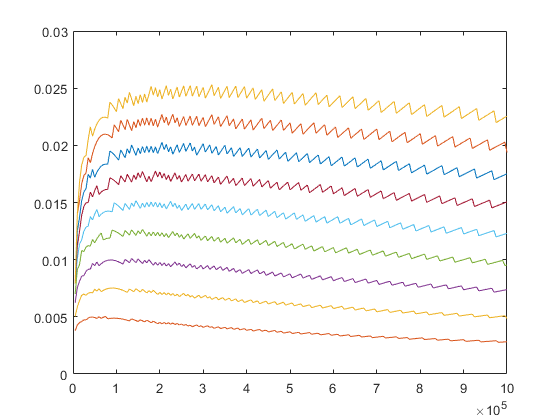

plot(K, USEEKVmax(:,i))
hold on
for i = 2:10
    plot(K, USEEKVmax(:,i))
end
hold off

% hold on
% for n = 1:size(K)
%     plot(K,USEEKVmax(n))
% end
hold off